## Group Assignment 2 - Image as a function, Image as a matrix, Convolution, etc.

1) You need 2 images. You can take new images or use your previous images. (a suggestion: try to use images where you think you will see something new in different color spaces).

% import images
miranda = imread('../images/IMAGE012.jpg');
computer = imread('../images/IMAGE001.jpg');

### Pixel Processing (Jiayuan)

1. Change brightness of your image

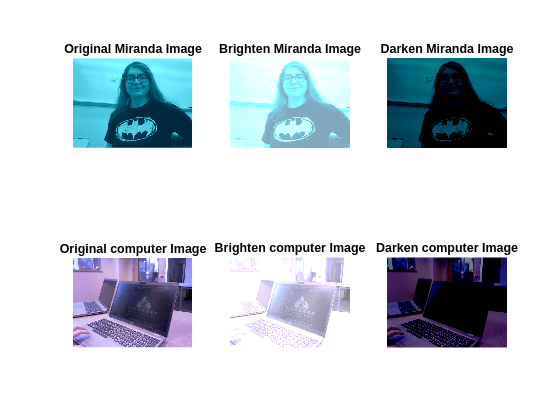

figure;
subplot(2,3,1);
imshow(miranda);
title('Original Miranda Image')

subplot(2,3,2);
miranda_bright = miranda + 128;
imshow(miranda_bright);
title('Brighten Miranda Image')

subplot(2,3,3);
miranda_dark = miranda - 128;
imshow(miranda_dark);
title('Darken Miranda Image')

subplot(2,3,4);
imshow(computer);
title('Original computer Image')

subplot(2,3,5);
computer_bright = computer + 128;
imshow(computer_bright);
title('Brighten computer Image')

subplot(2,3,6);
computer_dark = computer - 128;
imshow(computer_dark);
title('Darken computer Image')

2. Change contrast of your image

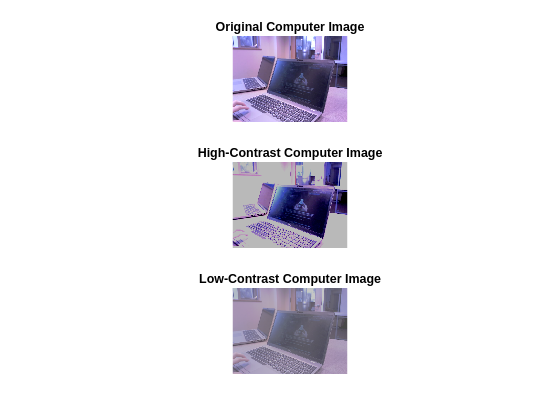

figure;
subplot(3,1,1);
imshow(computer);
title('Original Computer Image')

% shifted by 70 to "reset" brightness
subplot(3,1,2);
computer_highcon = computer *2 - 70;
imshow(computer_highcon);
title('High-Contrast Computer Image')

subplot(3,1,3);
computer_lowcon = computer / 2  + 70;
imshow(computer_lowcon);
title('Low-Contrast Computer Image')

3. Change brightness of alternating pixels of the image

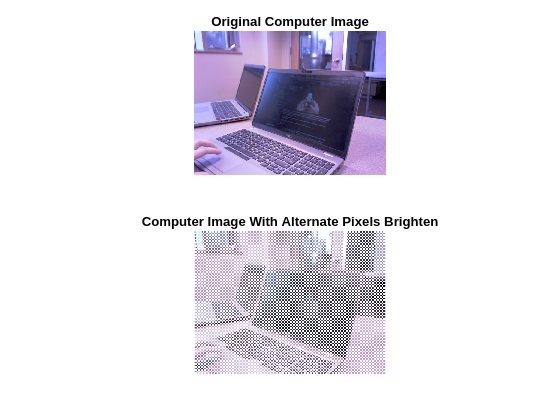

computer = imread('../images/IMAGE001.jpg');
computer_double = im2double(computer);
frame = size(computer);
mask = [];
mask_full = [];

for row = 1: frame(1)
    for col = 1 : frame(2)
        if (mod(row,2) == mod(col,2))
            mask(row, col) = 1;
        else 
            mask(row,col) = 0;
        end
    end
end 
mask_bright = mask * 10;

mask_full(:,:,1) = mask_bright;
mask_full(:,:,2) = mask_bright;
mask_full(:,:,3) = mask_bright;
computer_alt_bright = mask_full + computer_double;

figure
subplot(2,1,1);
imshow(computer_double)
title('Original Computer Image')

subplot(2,1,2);
imshow(computer_alt_bright)
title('Computer Image With Alternate Pixels Brighten')

### Color Spaces (Miranda)

- Show your images in the different color spaces we discussed. 

- Plot at least 4 different histograms  for each image from the various color spaces (e.g. you can do red,  green, saturation, value). 

- Were these color spaces useful for  your chosen image? Did they show something that you would not see in a  color or grayscale image? Did the histograms show something useful?

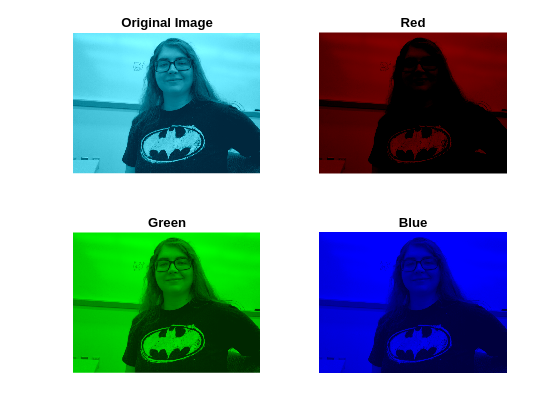

figure;
subplot(2,2,1);
imshow(miranda);
title('Original Image')

subplot(2,2,2);
miranda_R = miranda;
miranda_R(:,:,2) = 0;
miranda_R(:,:,3) = 0;
imshow(miranda_R);
title('Red')

subplot(2,2,3);
miranda_G = miranda;
miranda_G(:,:,1) = 0;
miranda_G(:,:,3) = 0;
imshow(miranda_G);
title('Green')

subplot(2,2,4);
miranda_B = miranda;
miranda_B(:,:,1) = 0;
miranda_B(:,:,2) = 0;
imshow(miranda_B);
title('Blue')

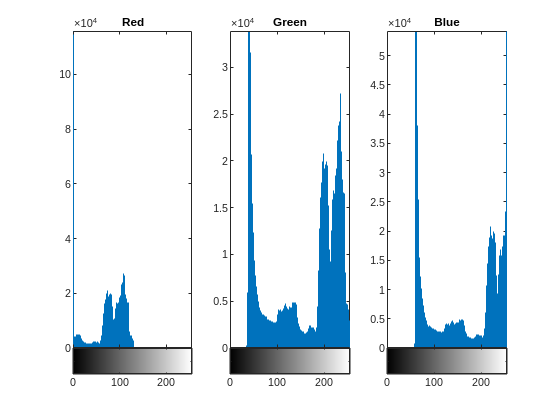


figure; 
[r,g,b] = imsplit(miranda);
subplot(1,3,1);
imhist(r)
title("Red")
subplot(1,3,2);
imhist(g)
title("Green")
subplot(1,3,3);
imhist(b)
title("Blue")

The color spaces did not show much about the image that couldn't be easily inferred from the original, partly because of the filter that the camera applied, making it mostly one color. 

These histograms are helpful for understanding the color fof that ilter on this image. There is very little red and much more green and blue. Additionally, the green and blue have similar shapes, just different sizes, indicating a very consistent teal hue throughout the image.

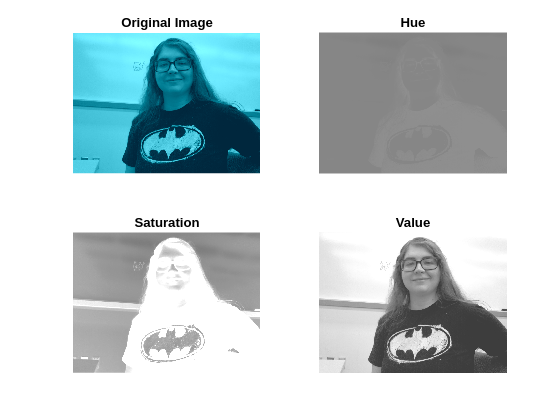

[h, s, v] = rgb2hsv(miranda);

figure;
subplot(2,2,1);
imshow(miranda);
title('Original Image')

subplot(2,2,2);
imshow(h);
title('Hue')

subplot(2,2,3);
imshow(s);
title('Saturation')

subplot(2,2,4);
imshow(v);
title('Value')

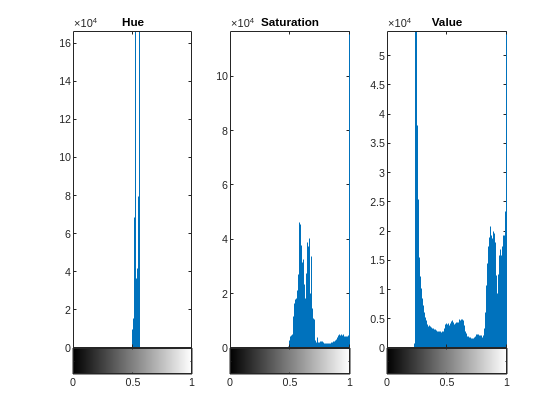


figure; 
subplot(1,3,1);
imhist(h)
title("Hue")
subplot(1,3,2);
imhist(s)
title("Saturation")
subplot(1,3,3);
imhist(v)
title("Value")

These imges and histograms tell a similar story to the RGB separation, but in a clearer way. Ther is very little variation in hue, as shown by the evenly gray hue representation and the thin peak at the center in the plot of hues. 

The saturation image did a pretty good job of isolating the human figure in the image, likely because of the contrast of dark clothes and hair against a light background. 

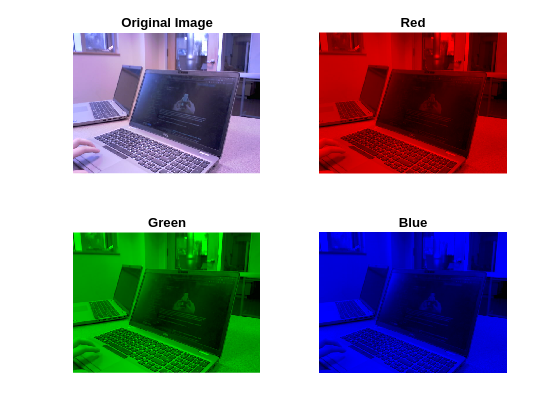

figure;
subplot(2,2,1);
imshow(computer);
title('Original Image')

subplot(2,2,2);
computer_R = computer;
computer_R(:,:,2) = 0;
computer_R(:,:,3) = 0;
imshow(computer_R);
title('Red')

subplot(2,2,3);
computer_G = computer;
computer_G(:,:,1) = 0;
computer_G(:,:,3) = 0;
imshow(computer_G);
title('Green')

subplot(2,2,4);
computer_B = computer;
computer_B(:,:,1) = 0;
computer_B(:,:,2) = 0;
imshow(computer_B);
title('Blue')

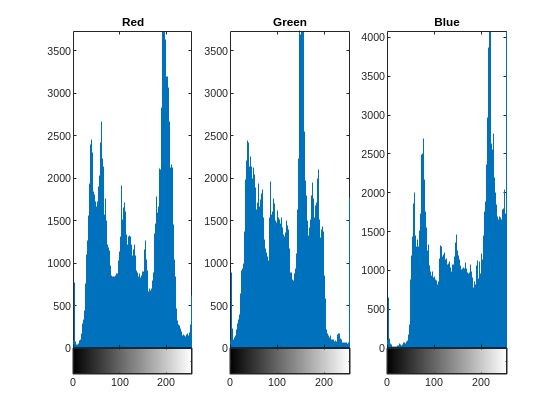

figure; 
[r,g,b] = imsplit(computer);
subplot(1,3,1);
imhist(r)
title("Red")
subplot(1,3,2);
imhist(g)
title("Green")
subplot(1,3,3);
imhist(b)
title("Blue")

The separated color spaces show some variation in where different colors exist in the image. One part that is easier to note is that the windows to the outside of the image have a more blue tint than the walls. This is shown in the histograms by the lack of much approx 210+ values in red and green but some of the highest amout of blue in that high range. 

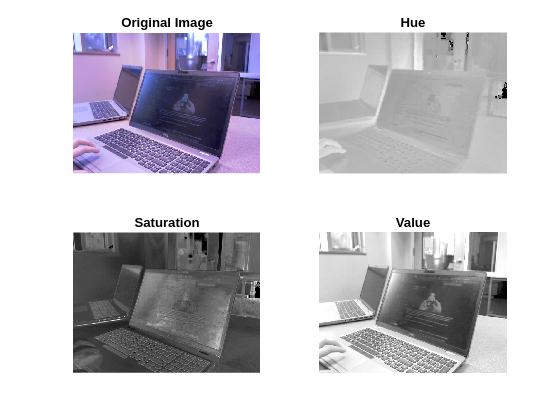

[h, s, v] = rgb2hsv(computer);

figure;
subplot(2,2,1);
imshow(computer);
title('Original Image')

subplot(2,2,2);
imshow(h);
title('Hue')

subplot(2,2,3);
imshow(s);
title('Saturation')

subplot(2,2,4);
imshow(v);
title('Value')

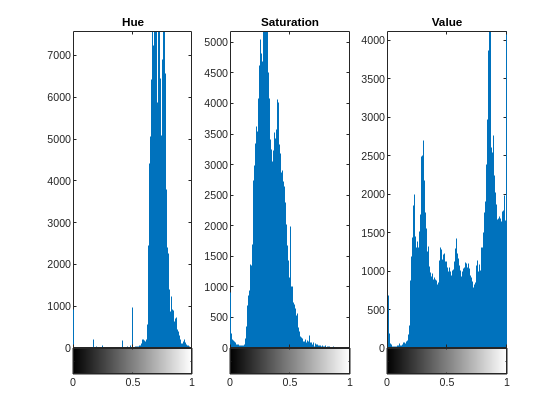

figure; 
subplot(1,3,1);
imhist(h)
title("Hue")
subplot(1,3,2);
imhist(s)
title("Saturation")
subplot(1,3,3);
imhist(v)
title("Value")

The hue color space image shows a few darker spots highlighting different colors occurring outside of the room, notably on the windows with some visible sky. The value is somewhat helpful for determing he locations of dark laptop screens. 

### Convolution/linear filtering (Gia)

Again, use 2 images - these can be same as before or different - your choice

Apply identity filter to both images, show results

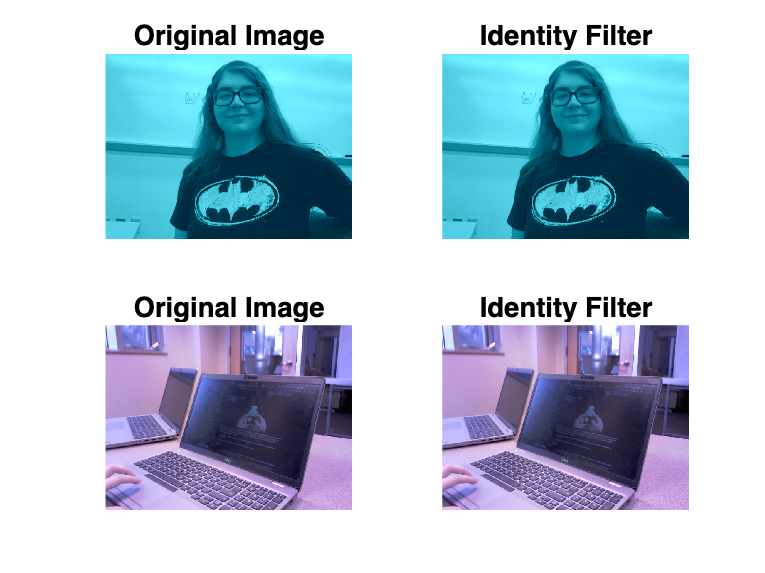

% Identity Filter
I = [0, 0, 0; 0, 1, 0; 0, 0, 0]; % identity filter

figure;
subplot(2,2,1);
imshow(miranda);
title('Original Image')

subplot(2,2,2);
miranda_I = imfilter(miranda, I, 'conv');
imshow(miranda_I);
title('Identity Filter')

subplot(2,2,3);
imshow(computer);
title('Original Image')

subplot(2,2,4);
computer_I = imfilter(computer_I, I, 'conv');
imshow(computer_I);
title('Identity Filter')

Apply box filter of 2 different sizes to both images, show results (that would be 4 images). 

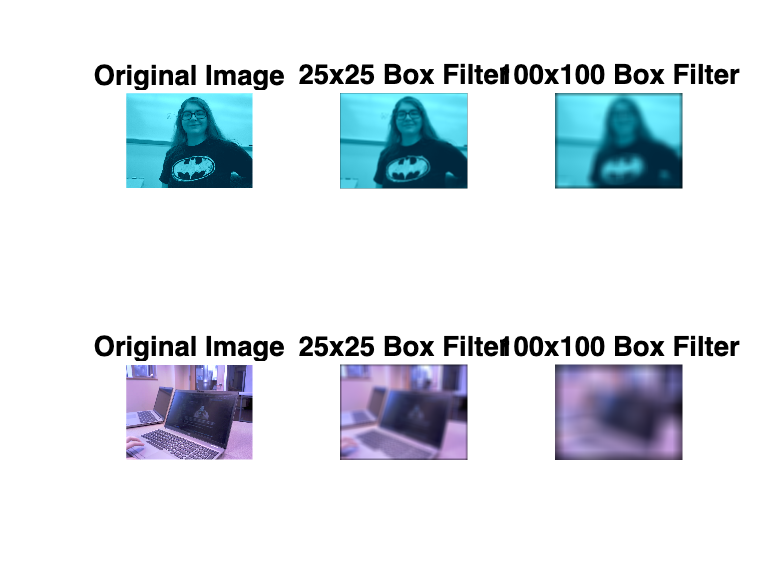

% Box Filter
size = 25;
size2 = 100;

B = 1/size^2 * ones(size); 
B2 = 1/size2^2 * ones(size2);

figure;
subplot(2,3,1);
imshow(miranda);
title('Original Image')

subplot(2,3,2);
miranda_B = imfilter(miranda, B, 'conv');
imshow(miranda_B);
title('25x25 Box Filter')

subplot(2,3,3);
miranda_B2 = imfilter(miranda, B2, 'conv');
imshow(miranda_B2);
title('100x100 Box Filter')

subplot(2,3,4);
imshow(computer);
title('Original Image')

subplot(2,3,5);
computer_B = imfilter(computer, B, 'conv');
imshow(computer_B);
title('25x25 Box Filter')

subplot(2,3,6);
computer_B2 = imfilter(computer, B2, 'conv');
imshow(computer_B2);
title('100x100 Box Filter')

Box filter was a blurring filter. Think about what a sharpening filter would look like and apply it to your 2 images.

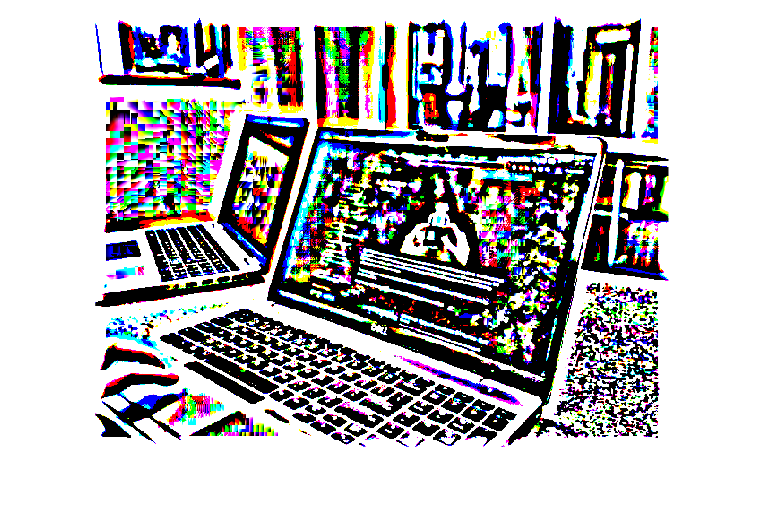

S2 = -1 * ones(size);
S2(13,13) = 25^2; 

computer_S = imfilter(computer, S2, 'conv');
figure;
imshow(computer_S);

Design a Gaussian filter with your  choice of variance. Apply this to your 2 images. Please mention what  variance you used in the image. 

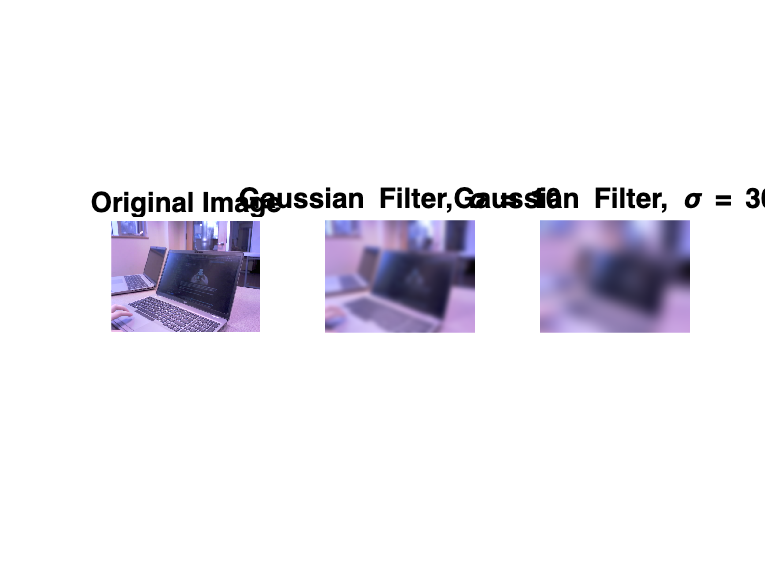

% Gaussian Filter
std = 10;
std2 = 30; % approximates miranda's myopia

figure;
subplot(1,3,1)
imshow(computer);
title('Original Image')

subplot(1,3,2)
computer_G = imgaussfilt(computer, std);
imshow(computer_G);
title('Gaussian Filter, \sigma = 10')

subplot(1,3,3)
computer_G2 = imgaussfilt(computer, std2);
imshow(computer_G2);
title('Gaussian Filter, \sigma = 30')

Bonus: Bit Plane Extraction

% % conversting to bitplane
% c0 = mod(cd, 2);
% c1 = mod(floor(cd/2), 2);
% c2 = mod(floor(cd/4), 2);
% c3 = mod(floor(cd/8), 2);
% c4 = mod(floor(cd/16), 2);
% c5 = mod(floor(cd/32), 2);
% c6 = mod(floor(cd/64), 2);
% c7 = mod(floor(cd/128), 2);
% 
% % reconstituted image
% cc = 2*(2*(2*(2*(2*(2*(2*c7+c6)+c5)+c4)+c3)+c2)+c1)+c0
